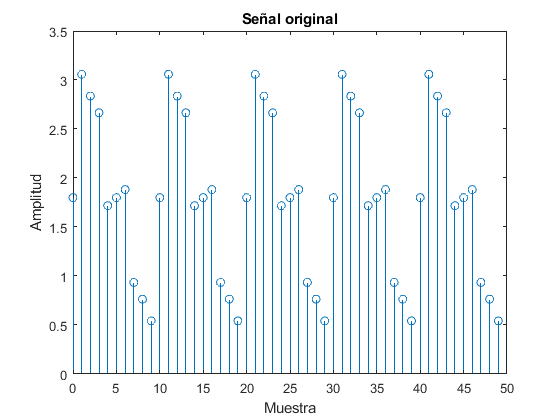

n=0:49;%tiempo
k=n/512;%frecuencias
xn=sin(2*pi*(50/500)*n)+0.55.*sin(2*pi*(100/500)*n)+0.25*sin(2*pi*(200/500)*n)+1.8;

% xn=datos1;
ordenFilt=3;
wc=60;
wcb=100;
wch=200;
xk=abs(fft(xn));

figure()
% subplot(2,1,1);
stem(n,xn);
title('Señal original');
xlabel('Muestra');
ylabel('Amplitud');

% subplot(2,1,2);
% stem(k,xk);
% title('Espectro de frecuencia');

%Filtro Butterworth
[b1,a1]=butter(ordenFilt,1/500,'low')

b1 = 	1.0e+-7 *

    0.3081    0.9244    0.9244    0.3081


a1 =     1.0000   -2.9874    2.9749   -0.9875


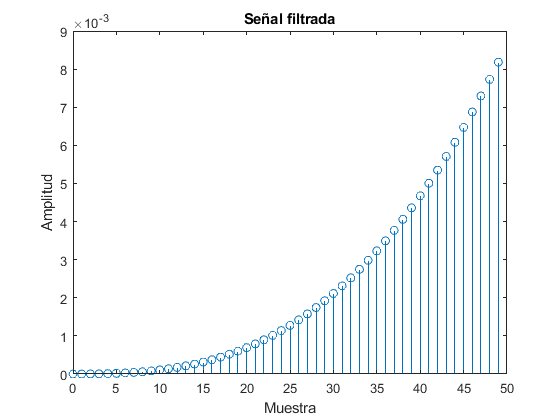

y1n=filter(b1,a1,xn);
y1k=abs(fft(y1n));
figure(2);
%freqz(b1,a1);

figure()
% subplot(2,1,1)
stem(n,y1n);
title('Señal filtrada');
xlabel('Muestra');
ylabel('Amplitud');

% subplot(2,1,2);
% stem(k,y1k);
% title('Espectro de frecuencia');

%Filtro Chebyshev tipo 1
[b2,a2]=cheby1(ordenFilt,0.5,wc/500)

b2 =     0.0038    0.0115    0.0115    0.0038


a2 =     1.0000   -2.4374    2.0926   -0.6246


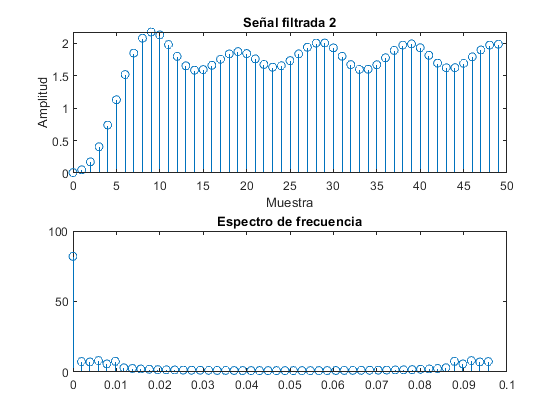

y2n=filter(b2,a2,xn);
y2k=abs(fft(y2n));
figure(2);
% freqz(b2,a2);

figure()
subplot(2,1,1);
stem(n,y2n);
title('Señal filtrada 2');
xlabel('Muestra');
ylabel('Amplitud');
subplot(2,1,2);
stem(k,y2k);
title('Espectro de frecuencia');


%Filtro Chebysev tipo 2
[b3,a3]=cheby2(ordenFilt,0.5,wch/500,"high")

b3 =     0.8673   -1.6180    1.6180   -0.8673


a3 =     1.0000   -1.6503    1.5685   -0.7517


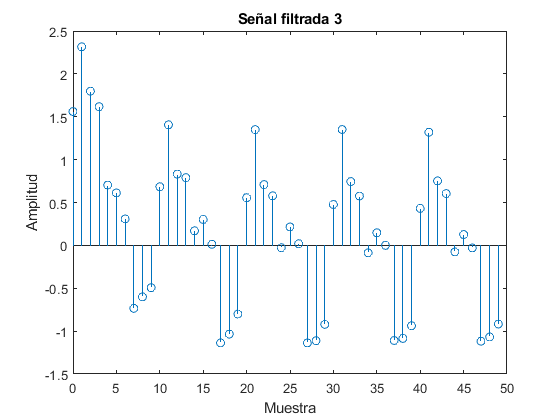

y3n=filter(b3,a3,xn);
y3k=abs(fft(y3n));
figure(2);
% freqz(b3,a3);

figure()
% subplot(2,1,1)
stem(n,y3n);
title('Señal filtrada 3');
xlabel('Muestra');
ylabel('Amplitud');

% subplot(2,1,2);
% stem(k,y3k);
% title('Espectro de frecuencia');

%Filtro eliptico tipo 2
[b4,a4]=ellip(ordenFilt,0.5,20,wc/500)

b4 =     0.0586   -0.0391   -0.0391    0.0586


a4 =     1.0000   -2.4435    2.1129   -0.6304


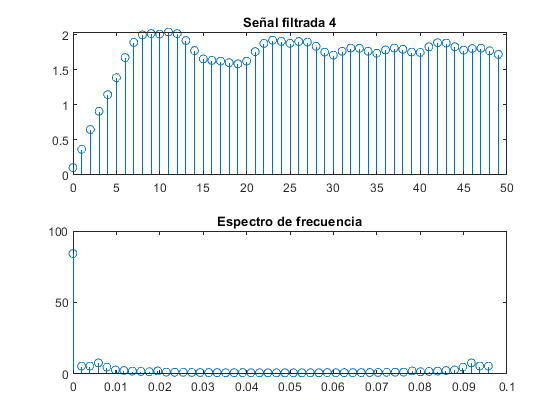

y4n=filter(b4,a4,xn);
y4k=abs(fft(y4n));
figure(2);
% freqz(b4,a4);

figure()
subplot(2,1,1)
stem(n,y4n);
title('Señal filtrada 4');
subplot(2,1,2);
stem(k,y4k);
title('Espectro de frecuencia');